# Solving linear least squares problems and linear regression

The linear least squares problem is


$$\min_w \| y - X w \|_2^2$$


where $y$ is a given $n \times 1$ vector, $X$ is a given $n \times m$ matrix with $n > m$, and $w$ is a $m \times 1$ vector to be determined. This problem arises in linear regression and countless other applications.

Assume that $X$ has a linear independent set of columns. Then, one way to solve for $w$ is to solve the *normal equations,*


$$X^T X w = X^T y$$


which is a linear system of $m$ equations and $m$ unknowns that can be solved via Cholesky factorization. From this equation, the vector $w$ can be written explicitly as


$$w = (X^T X)^{-1} X^T y$$


which can be called the *formal solution* to the least squares problem.

It is essential to point out whenever introducing the normal equations that solving the least squares problem this way is not numerically stable, and thus not guaranteed to give an accurate answer, due to accumulation of roundoff error in a computer calculation. A numerically stable way to solve the least squares problem is to use QR factorization.

Thus you should never solve the least squares problem via the normal equations unless you understand the risks. The formal solution is often written down as the least-squares solution when working analytically where numerical computations are not being performed, but it is just that: a formal solution, but not one intended for computations.

### Example

We now show an example of the differences you obtain in the answers when you solve the least squares problem using the normal equations and using QR factorization.

First generate a matrix $X$ of size $n \times 2$. Ignore how this matrix is generated for now.

rng(0)
n = 10;
X = rand(n,1)-.5;
X = [X X+rand(n,1)*1e-8];

Since we want to compare the answers from our numerical computations, let's set up the problem so that we know the true $w$.

w = [1 2]';

Generate the vector $y$ with this known solution.

y = X*w;

Now we are ready to solve using the normal equations

format long
fprintf('Solution using normal equations\n');

Solution using normal equations


w = (X'*X)\(X'*y)

w =    0.895865132745946
   2.104134866327875


and using QR factorization

fprintf('Solution using QR factorization\n');

Solution using QR factorization


[Q, R] = qr(X,0); % Q is n by 2
w = R\(Q'*y)

w =    0.999999994878468
   2.000000005121533


Observe that the solution using the normal equations can be quite inaccurate, while the solution via QR factorization is much more accurate. Although the solution methods are *mathematically* equivalent, they are *numerically* different. This phenomenon occurs not just for least squares problems but for all problems that are solved on a computer with floating point computations. We must avoid numerically unstable methods that tend to incur large amounts of roundoff error that can spoil an answer. The study of stable and unstable algorithms is a major part of the field of Numerical Analysis.

Returning back to our example, if the matrix $X$ has more rows than columns, which is the setting of our least squares problem, then the [backslash operator](https://www.mathworks.com/help/matlab/ref/mldivide.html) in MATLAB will automatically return the least squares solution (using a stable method).

fprintf('Solution using Matlab\n');

Solution using Matlab


w = X\y

w =    1.000000000984840
   1.999999999015160


### Taking it further

- Experiment with different ways of generating the matrix $X$ and observe how the numerical least squares solutions compare when using the normal equations and using QR factorization. Explain in what cases the normal equations solution is accurate.

- What happens if the columns of $X$ are not linearly independent? How do the three numerical solutions above compare to the true solution? What is the residual $r=y-Xw$ for the different numerical solutions $w$? Note that the residual can be small for different $w$, suggesting that they are all possible solutions.

- We did not explain the linear least squares solution method that uses QR factorization. Investigate this method as well as what should be done if $X$ does not have linearly independent columns.

### Linear regression

Now that you know how to solve least squares problem in a stable fashion, let's use it to solve a simple 1-dimensional linear regression problem.

Here is an example using three data points.

x = [1.0 2.0 3.0]';
y = [5.1 6.2 7.1]';

Set up the matrix $X$ for linear regression.

n = length(x);
X = [ones(n,1) x];

Solve the least squares problem.

w = X\y;

Plot the data and the linear regression line.

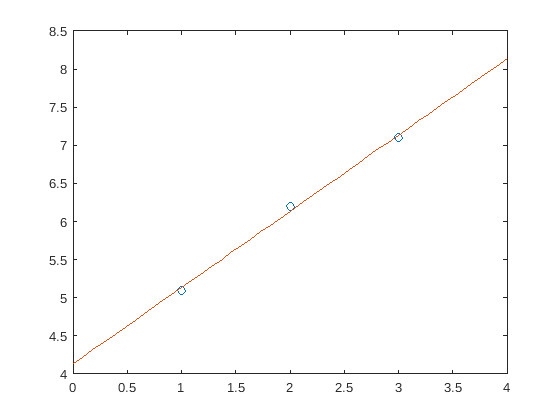

clf
plot(x,y,'o');
hold on
fun = @(x) w(1)+w(2)*x;
fplot(fun, [0 4]);

### Taking it further

Construct a 2-dimensional multiple regression problem (i.e., fabricate the data) such that the least squares solution via the normal equations is inaccurate (but accurate via the QR factorization method).